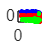

% 进行标定数据与雷达数据的映射工作，并作图
readData;
[LaneRadarTrack1] = mapLane2Radar(RadarData, Lane1);
[LaneRadarTrack2] = mapLane2Radar(RadarData, Lane2);
[LaneRadarTrack3] = mapLane2Radar(RadarData, Lane3);
LaneRadarTrack1_choose = LaneRadarTrack1;
LaneRadarTrack2_choose = LaneRadarTrack2;
LaneRadarTrack3_choose = LaneRadarTrack3;
figure(1)
plot(LaneRadarTrack1_choose(:, 2), LaneRadarTrack1_choose(:, 3),'b.')
hold on
plot(LaneRadarTrack2_choose(:, 2), LaneRadarTrack2_choose(:, 3),'r.')
plot(LaneRadarTrack3_choose(:, 2), LaneRadarTrack3_choose(:, 3),'g.')

% 剔除标定数据与雷达数据的映射中不合理的数据点，并作图
LaneRadarTrack1_choose = LaneRadarTrack1_choose(LaneRadarTrack1_choose(:, 3) > 1.5, :);
LaneRadarTrack1_choose = LaneRadarTrack1_choose(LaneRadarTrack1_choose(:, 3) < 4.5, :);

LaneRadarTrack2_choose = LaneRadarTrack2_choose(LaneRadarTrack2_choose(:, 3) > -2, :);
LaneRadarTrack2_choose = LaneRadarTrack2_choose(LaneRadarTrack2_choose(:, 3) < 1, :);

LaneRadarTrack3_choose = LaneRadarTrack3_choose(LaneRadarTrack3_choose(:, 3) > -5.5, :);
LaneRadarTrack3_choose = LaneRadarTrack3_choose(LaneRadarTrack3_choose(:, 3) < -2.5, :);

figure(1)
hold on
plot(LaneRadarTrack1_choose(:, 2), LaneRadarTrack1_choose(:, 3),'.')
plot(LaneRadarTrack2_choose(:, 2), LaneRadarTrack2_choose(:, 3),'.')
plot(LaneRadarTrack3_choose(:, 2), LaneRadarTrack3_choose(:, 3),'.')

% figure(2)
% plot(LaneRadarTrack1(:, 2), LaneRadarTrack1(:, 3),'.')
% figure(3)
% plot(LaneRadarTrack2(:, 2), LaneRadarTrack2(:, 3),'.')
% figure(4)
% plot(LaneRadarTrack3(:, 2), LaneRadarTrack3(:, 3),'.')


% 将雷达点云数据分为零速点，界外正速点，界外负速点，界内正速点，界内负速点，并作图

[k1, b1] = line_plofit(LaneRadarTrack1(:, 2), LaneRadarTrack1(:, 3));
[k2, b2] = line_plofit(LaneRadarTrack2(:, 2), LaneRadarTrack2(:, 3));
[k3, b3] = line_plofit(LaneRadarTrack3(:, 2), LaneRadarTrack3(:, 3));

k = (k1 + k2 + k3) / 3;
[b_left, b_right] = get_intercept(k, b1, b3);
n_radar_data = size(RadarData, 1);

x_plot = 1 : 400;
y_plot1 = k * x_plot + b_left;
y_plot2 = k * x_plot + b_right;
figure(1)
hold on
plot(x_plot, y_plot1, 'k','DisplayName','四车道边缘1')
plot(x_plot, y_plot2, 'k','DisplayName','四车道边缘2')
idx_in_or_not = zeros(n_radar_data, 1);

% 判断界内或界外
for i = 1 : n_radar_data
    if check_in_zone(k, b_left, b_right, RadarData(i, 3), RadarData(i, 4))
        idx_in_or_not(i) = 1;
    end
end
[idx_IN, ~] = find(idx_in_or_not);
[idx_NOT_IN, ~] = find(~idx_in_or_not);

% 判断非零与否
idx_V_ZERO_OR_NOT = zeros(n_radar_data, 1);
for i = 1 : n_radar_data
    if RadarData(i, 5) == 0
        idx_V_ZERO_OR_NOT(i) = 1;
    end

end
[idx_V_ZEROS, ~] = find(idx_V_ZERO_OR_NOT);
[idx_V_NOT_ZEROS, ~] = find(~idx_V_ZERO_OR_NOT);

% 判断界内的点的速度正负
idx_POS_OR_NOT = zeros(length(idx_IN), 1);
for i = 1 : length(idx_IN)
    if RadarData(idx_IN(i), 5) > 0
        idx_POS_OR_NOT(i) = 1;
    elseif RadarData(idx_IN(i), 5) < 0
         idx_POS_OR_NOT(i) = 2;
    end
end
[idx_IN_POS, ~] = find(idx_POS_OR_NOT == 1);
idx_IN_POS = idx_IN(idx_IN_POS);
[idx_IN_NEG, ~] = find(idx_POS_OR_NOT == 2);
idx_IN_NEG = idx_IN(idx_IN_NEG);

% 判断界外的点的速度正负
idx_POS_OR_NOT = zeros(length(idx_NOT_IN), 1);
for i = 1 : length(idx_NOT_IN)
    if RadarData(idx_NOT_IN(i), 5) > 0
        idx_POS_OR_NOT(i) = 1;
    elseif RadarData(idx_NOT_IN(i), 5) < 0
         idx_POS_OR_NOT(i) = 2;
    end
end
[idx_OUT_POS, ~] = find(idx_POS_OR_NOT == 1);
idx_OUT_POS = idx_NOT_IN(idx_OUT_POS);
[idx_OUT_NEG, ~] = find(idx_POS_OR_NOT == 2);
idx_OUT_NEG = idx_NOT_IN(idx_OUT_NEG);

% scatter(RadarData(idx_NOT_IN, 3), RadarData(idx_NOT_IN, 4), 0.01, 'r.', 'DisplayName','界外有速数据点')
% scatter(RadarData(idx_IN, 3), RadarData(idx_IN, 4), 0.01, 'g.', 'DisplayName','界内有速数据点')
% scatter(RadarData(idx_V_ZEROS, 3), RadarData(idx_V_ZEROS, 4), 0.01, 'b.', 'DisplayName', '零速数据点')

scatter3(RadarData(idx_OUT_POS, 3), RadarData(idx_OUT_POS, 4), RadarData(idx_OUT_POS, 5), 0.01, 'r.', 'DisplayName','界外正速数据点')
scatter3(RadarData(idx_OUT_NEG, 3), RadarData(idx_OUT_NEG, 4), RadarData(idx_OUT_NEG, 5), 0.01, 'm.', 'DisplayName','界外负速数据点')
scatter3(RadarData(idx_IN_POS, 3), RadarData(idx_IN_POS, 4), RadarData(idx_IN_POS, 5), 0.01, 'g.', 'DisplayName','界内正速数据点')
scatter3(RadarData(idx_IN_NEG, 3), RadarData(idx_IN_NEG, 4), RadarData(idx_IN_NEG, 5), 0.01, '.', 'MarkerEdgeColor', [0.25, 0.7, 0.02], 'DisplayName','界内负速数据点')
scatter3(RadarData(idx_V_ZEROS, 3), RadarData(idx_V_ZEROS, 4), RadarData(idx_V_ZEROS, 5), 0.01, 'b.', 'DisplayName', '零速数据点')

% Create ylabel
ylabel({'横向距离y/m'},'FontSize',18);
% Create xlabel
xlabel({'纵向距离x/m'},'FontSize',18);
legend1 = legend('show');
set(legend1,'FontSize',12);
legend("boxoff")

% 遍历闰秒参数，0.001作步长，17~20s
spGap1_1 = zeros(3000, 1);
spGap2_1 = zeros(3000, 1);
spGap3_1 = zeros(3000, 1);
spGap1_2 = zeros(3000, 1);
spGap2_2 = zeros(3000, 1);
spGap3_2 = zeros(3000, 1);
for i = 1 : 3000
    [LaneRadarTrack1] = mapLane2Radar(RadarData, Lane1, 17 + i / 1000);
    spGap1_1(i) = mean(abs(LaneRadarTrack1(:, 14))); % Track1: min_val = 0.0691771, min_idx = 856
    spGap1_2(i) = mean(abs(LaneRadarTrack1(:, 12)));
    [LaneRadarTrack2] = mapLane2Radar(RadarData, Lane2, 17 + i / 1000);
    spGap2_1(i) = mean(abs(LaneRadarTrack2(:, 14)));    % Track2: min_val = 0.0812516985584016, min_idx = 830
    spGap2_2(i) = mean(abs(LaneRadarTrack2(:, 12)));
    [LaneRadarTrack3] = mapLane2Radar(RadarData, Lane3, 17 + i / 1000);
    spGap3_1(i) = mean(abs(LaneRadarTrack3(:, 14))); % Track3: min_val = 0.0780745007045093, min_idx = 975
    spGap3_2(i) = mean(abs(LaneRadarTrack3(:, 12)));
    % fprintf('%d\n%', i)
end
[min_val1_1, min_idx1_1] = min(spGap1_1); 
[min_val2_1, min_idx2_1] = min(spGap2_1); 
[min_val3_1, min_idx3_1] = min(spGap3_1);

[min_val1_2, min_idx1_2] = min(spGap1_2); 
[min_val2_2, min_idx2_2] = min(spGap2_2); 
[min_val3_2, min_idx3_2] = min(spGap3_2); 


% 通过标定数据，确定雷达坐标系的原点的经纬度
[k1, b1] = line_plofit(LaneRadarTrack1(:, 2), LaneRadarTrack1(:, 3));
[k2, b2] = line_plofit(LaneRadarTrack2(:, 2), LaneRadarTrack2(:, 3));
[k3, b3] = line_plofit(LaneRadarTrack3(:, 2), LaneRadarTrack3(:, 3));
k = (k1 + k2 + k3) / 3;
tan1 = LaneRadarTrack1(:, 6) ./ LaneRadarTrack1(:, 7);
tan2 = LaneRadarTrack2(:, 6) ./ LaneRadarTrack2(:, 7);
tan3 = LaneRadarTrack3(:, 6) ./ LaneRadarTrack3(:, 7);
arcTan1 = atan(tan1);
arcTan2 = atan(tan2);
arcTan3 = atan(tan3);
latitudeMean = mean([LaneRadarTrack1(:, 4); LaneRadarTrack2(:, 4); LaneRadarTrack3(:, 4)]); % 平均纬度
theta1 = mean([arcTan1; arcTan2; arcTan3]); % 经纬度与雷达坐标系之间的角度偏差
theta2 = atan(k);   % 车道与雷达坐标系之间的角度偏差
theta0 = theta1 - theta2;

[ori_longitude, ori_latitude] = cal_ori_lat_and_long(theta0, LaneRadarTrack1, LaneRadarTrack2, LaneRadarTrack3);
figure(1)
plot(LaneRadarTrack1(:, 5), LaneRadarTrack1(:, 4),'go', 'MarkerSize', 2, 'LineWidth', 0.1)
hold on
plot(LaneRadarTrack2(:, 5), LaneRadarTrack2(:, 4),'go', 'MarkerSize', 2, 'LineWidth', 0.1)
plot(LaneRadarTrack3(:, 5), LaneRadarTrack3(:, 4),'go', 'MarkerSize', 2, 'LineWidth', 0.1)
plot(ori_longitude, ori_latitude, 'r+', 'MarkerSize', 10, 'LineWidth', 2)

[longitude1, latitude1] = getCoordinate(LaneRadarTrack1(:, 2), LaneRadarTrack1(:, 3), theta0, latitudeMean, ori_longitude, ori_latitude);
[longitude2, latitude2] = getCoordinate(LaneRadarTrack2(:, 2), LaneRadarTrack2(:, 3), theta0, latitudeMean, ori_longitude, ori_latitude);
[longitude3, latitude3] = getCoordinate(LaneRadarTrack3(:, 2), LaneRadarTrack3(:, 3), theta0, latitudeMean, ori_longitude, ori_latitude);

plot(longitude1, latitude1,'r^', 'MarkerSize', 2, 'LineWidth', 0.1)
plot(longitude2, latitude2,'r^', 'MarkerSize', 2, 'LineWidth', 0.1)
plot(longitude3, latitude3,'r^', 'MarkerSize', 2, 'LineWidth', 0.1)

n_data= size(final_data, 1);
[carIDNum, uniqueCarID] = groupcounts(final_data(:, 2));
uniqueCarNum = length(carIDNum);
figure(3)
hold on
for i = 1 : uniqueCarNum
    idx = find(final_data(:, 2) == uniqueCarID(i));
    if final_data(idx(1), 5) == 0
        continue;
    end
    plot3(final_data(idx, 3), final_data(idx, 4), final_data(idx, 1))
end
